## **Mahalanobis distance as used in cluster analysis**

The Mahalanobis distance measures the distance between a point and a mean, taking into account the covariance structure of the data. It is therefore a scale- and correlation-adjusted distance — perfect for outlier detection, multivariate normal distributions, clustering, PCA, and machine learning.

For a data point x, the mean vector μ, and the covariance matrix Σ:

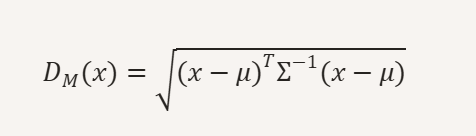

Characteristics of the distance measurement:

- Takes into account **correlations between variables**. Points along the direction of the principal component appear “closer.”

- **Scale-independent. **Whether it's centimeters, kilograms, or seconds, everything is automatically normalized.

- **Elliptical distance instead of a circle. **In a multivariate normal distribution, the isodistance lines are ellipses.

%% Mahalanobis Demo with Multiple Clusters
% Decision Regions + Covariance Ellipses

clear;
clc;

%% --------------------------------------------------------
%% Local Mahalanobis functions
%% --------------------------------------------------------

function d = mahalanobis(x,mu,Sigma)

dx = x - mu;

d = sqrt(dx * (Sigma \ dx'));

end

function plotEllipse(mu,Sigma,r,col)

t = linspace(0,2*pi,300);

C = chol(Sigma);

E = (mu' + C' * (r * [cos(t);sin(t)]))';

plot(E(:,1),E(:,2), ...
    'Color',col, ...
    'LineWidth',1.5);

end

%% ---------------------------------------------------------


## Generate Sample Data:


%% Reproducibility

rng(1);

%% Create a cluster

N = 200;

X1 = mvnrnd([2 3], [3 1.5; 1.5 2], N);
X2 = mvnrnd([8 7], [2 0.5; 0.5 1], N);
X3 = mvnrnd([6 2], [1 -0.7; -0.7 2], N);


## Save as a CSV file for possible use in another program (R, C++, ...):

labels = [
    ones(N,1);
    2*ones(N,1);
    3*ones(N,1)
    ];

X = [X1; X2; X3];

Datamatrix = [X labels];

%% Save data and display preview
writematrix(Datamatrix, 'C:\Temp\MahalanobisData.csv', 'WriteMode','overwrite');
fprintf('Dataset with %d data points saved.\n', size(Datamatrix, 1));

Dataset with 600 data points saved.


## Calculate distance and display it graphically:

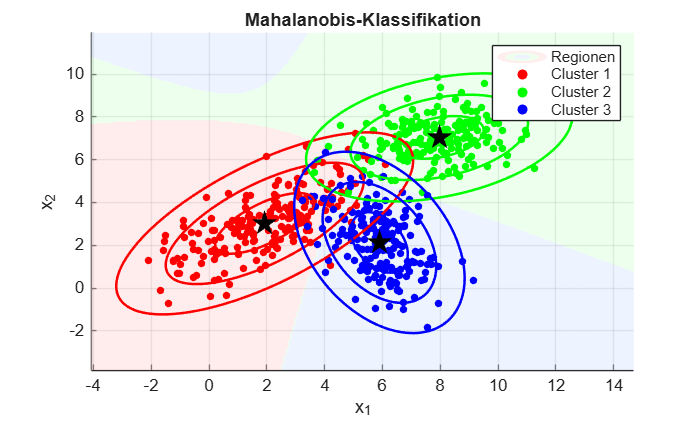



%% Cluster Parameters

mu1 = mean(X1);
S1  = cov(X1);

mu2 = mean(X2);
S2  = cov(X2);

mu3 = mean(X3);
S3  = cov(X3);


xmin = min([X1(:,1); X2(:,1); X3(:,1)]) - 2;
xmax = max([X1(:,1); X2(:,1); X3(:,1)]) + 2;

ymin = min([X1(:,2); X2(:,2); X3(:,2)]) - 2;
ymax = max([X1(:,2); X2(:,2); X3(:,2)]) + 2;


[xg, yg] = meshgrid(linspace(xmin,xmax,250),linspace(ymin,ymax,250));

classmap = zeros(size(xg));

%% Mahalanobis Classification

for k = 1:numel(xg)

    p = [xg(k) yg(k)];

    d1 = mahalanobis(p,mu1,S1);
    d2 = mahalanobis(p,mu2,S2);
    d3 = mahalanobis(p,mu3,S3);

    [~,idx] = min([d1 d2 d3]);

    classmap(k) = idx;

end

%% Presentation

figure('Color','w');

hold on;
grid on;
%%axis equal;


%% Decision-Making Regions

contourf(xg, yg, classmap, [0.5 1.5 2.5 3.5], 'LineStyle','none', FaceAlpha=0.45);

colormap([
    1.0 0.85 0.85
    0.85 1.0 0.85
    0.85 0.90 1.0
]);

alpha(0.35);

%% Points

scatter(X1(:,1),X1(:,2),20, 'r','filled');
scatter(X2(:,1),X2(:,2),20, 'g','filled');
scatter(X3(:,1),X3(:,2),20, 'b','filled');

%% Centers

plot(mu1(1),mu1(2),'kp', 'MarkerSize',14, 'MarkerFaceColor','k');
plot(mu2(1),mu2(2),'kp', 'MarkerSize',14, 'MarkerFaceColor','k');
plot(mu3(1),mu3(2),'kp', 'MarkerSize',14, 'MarkerFaceColor','k');

%% Mahalanobis ellipses

plotEllipse(mu1,S1,1,'r');
plotEllipse(mu1,S1,2,'r');
plotEllipse(mu1,S1,3,'r');

plotEllipse(mu2,S2,1,'g');
plotEllipse(mu2,S2,2,'g');
plotEllipse(mu2,S2,3,'g');

plotEllipse(mu3,S3,1,'b');
plotEllipse(mu3,S3,2,'b');
plotEllipse(mu3,S3,3,'b');


title('Mahalanobis Classification');
xlabel('x_1');
ylabel('x_2');

legend( ...
    'Regions', ...
    'Cluster 1', ...
    'Cluster 2', ...
    'Cluster 3');

hold off;

disp(['Center X1 = ', num2str(mu1)]);

Center X1 = 1.925      3.0229


disp(['Center X2 = ', num2str(mu2)]);

Center X2 = 7.9657      7.0399


disp(['Center X3 = ', num2str(mu3)]);

Center X3 = 5.8955      2.1348


%% End of script